# Assignment 4 

# Determining and removing drawbacks of exponential and running mean. Task 2

## by 

Group 19 

Ahmed Baza , skoltech, 2020 

Ahmed Elgohary , skoltech, 2020 

Moahmed Sayed , skoltech, 2020 

Ziad Baraka , skoltech, 2020 

## **Part 1) Comparison of the traditional 13-month running mean with the forward-backward exponential smoothing for approximation of 11-year sunspot cycle.**

**1.1) **we used the data assigned to us (data group 5) and gnerated the traditional 13-month running mean smoothing as per assignment 1, ploting the results for visualization.

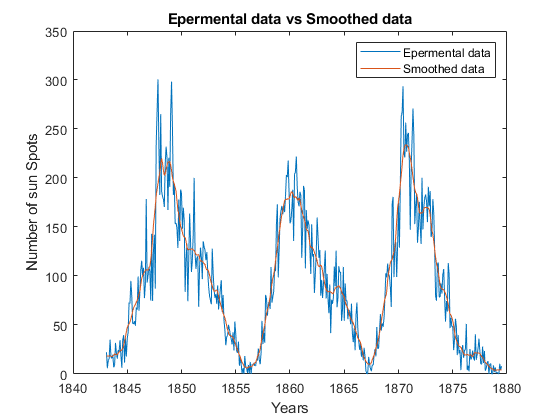

clc
clear 
load('data_group5.mat'); % loading data. 
Years_axis=data(:,1)+(1/12)*data(:,2);
R=data(:,3); % sunspot number 
N=length(R);
RS=R;                     % arrays for the smoothing results. 
for i=7:N-6  %running mean smoothing with window size= 13
  RS(i)=1/24*(R(i-6)+R(i+6))+1/12*sum(R(i-5:i+5));
end
RS(1:6)=mean(R(1:6)); RS(N-5:N)=mean(R(N-5:N)); 
figure()
plot(Years_axis,R,Years_axis,RS); 
title('Epermental data vs Smoothed data'); 
legend('Epermental data','Smoothed data')
xlabel('Years')
ylabel('Number of sun Spots'); 

`figure(1) gnerated  traditional 13-month running mean smoothing`

In this graph the running mean is plotted along with the measurements of sunspot data, and by analyzing the graph visually it can be verified that it follows the trend of the measurements to a good extent. 

**1.2) **then we calculated the deviation and variability indecators that will be used to determin the optimal $\alpha \;$later on. 

Id_RM=sum((R-RS).^2); %deviation Indecator of running mean smoothing 
Iv_RM=varI(RS); % Variabelity indecator of running mean smoothing 

**1.3) **Based on the values of the deviation and variability indecators of  the running mean we evaluated the $\alpha \;$that can prduce less values of bothe indecators (better smoothing): 

k=1;
for alpha=0:0.01:0.9
                       %Forward Exponintial Smoothing 
        RF=R; 
    for i=2:N
        RF(i)=alpha*R(i)+(1-alpha)*RF(i-1);
    end
                       % Backward Exponintial Smoothing 
    RB=RF; 
    for i=N-1:-1:1
        RB(i)=alpha*RF(i)+(1-alpha)*RB(i+1);
    end
    Id_BS=sum((R-RB).^2); %deviation Indecator of forward-backward smoothing.
    Iv_BS=varI(RB); % Variabelity indecator of forward-backward smoothing.
    if Id_BS<Id_RM && Iv_BS<Iv_RM
        alphaM(k)=alpha;
        k=k+1;
    end
end
disp(alphaM);

    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500



Using deviation and variability indicators, we tested different values of alpha from 0 to 0.9 with an 0.01 step, and our criteria was to have lower value for both Id, Iv for the exponential smoothing compared to the values of the running mean we estimated $\alpha \;$[0.18:0.25]. we used smaller step of 0.001 to better estimat the range, We found the range that alphas that follows our criteria for Id and Iv was between 0.174 to 0.259.

 The plot here shows the values with 0.01 step for better visualization.

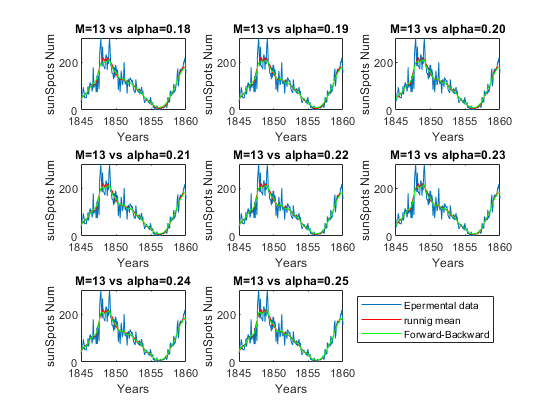

figure()
for j=1:length(alphaM)
    alpha=alphaM(j);
      RF=R; 
                       % forward Exponitial smothing 
    for i=2:N 
        RF(i)=alpha*R(i)+(1-alpha)*RF(i-1);
    end
                       % Backward Exponintial Smoothing 
    RB=RF; 
    for i=N-1:-1:1
        RB(i)=alpha*RF(i)+(1-alpha)*RB(i+1);
    end
    subplot(3,3,j)
    plot(Years_axis,R,Years_axis,RS,'r',Years_axis,RB,'g'); 
    s='M=13 vs alpha=';
    s2=sprintf('%.2f',alpha); 
    s3=strcat(s,s2); 
    title(s3); 
    xlabel('Years')
    ylabel('sunSpots Num'); 
    xlim([1845 1860])
end
subplot(3,3,9)
plot(0,0,0,0,'r',0,0,'g')
axis off
legend('Epermental data','runnig mean','Forward-Backward')

`figure(2) Runnimg mean vs diffrent values of `$\alpha \;$

`the graph is zoomed on the period [1845 1860] for better visuaiziation of the curves `

 The diffrence between the two smoothing methods isn't very noticeable visually except for on the peaks, the forward=backward smoothing had smaller values on the sudden jumps kepping the curve more smoothed. 

## Part2  3d surface filtration using forward-backward smoothing

for this part we worked with data set 3. 

**2.1) loading the data and ploting the noisy and the trur surfuce: **

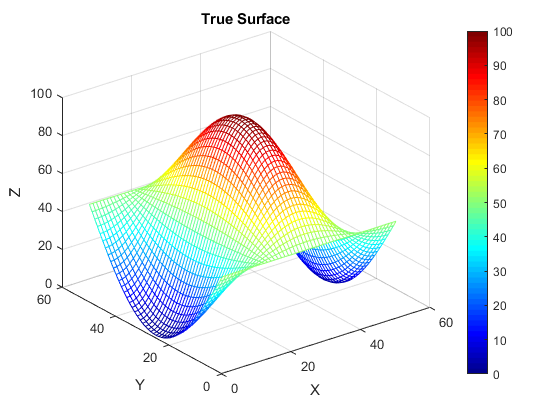

load('noisy_surface.mat');
load('true_surface.mat');
figure()
mesh(true_surface) % plotting true surface. 
colormap jet
colorbar 
title('True Surface');  xlabel('X'); ylabel('Y'); zlabel('Z')

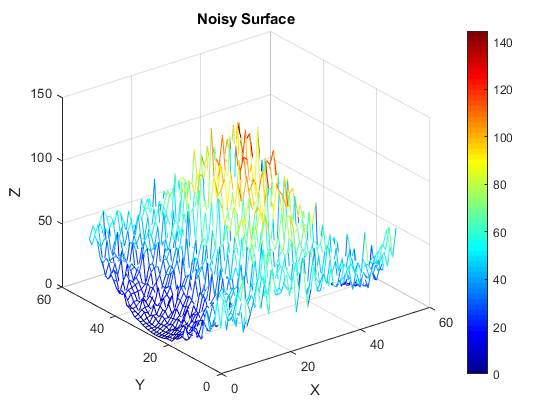

mesh(noisy_surface)
colormap jet
colorbar 
title('Noisy Surface'); xlabel('X'); ylabel('Y'); zlabel('Z');

`figure(3) plotting the true surface and the noisy surface. `

` we can see the noisiness of the data compared the true surfuce.` 

**2.2) calculating the variance: **

True=reshape(true_surface,[],1);
Noisy=reshape(noisy_surface,[],1);
Varianc=(1/(length(True)-1))*sum((Noisy-True).^2)

Varianc = 120.6820

**2.3) Applying forward Backward smoothing and reconstructing the surface. **

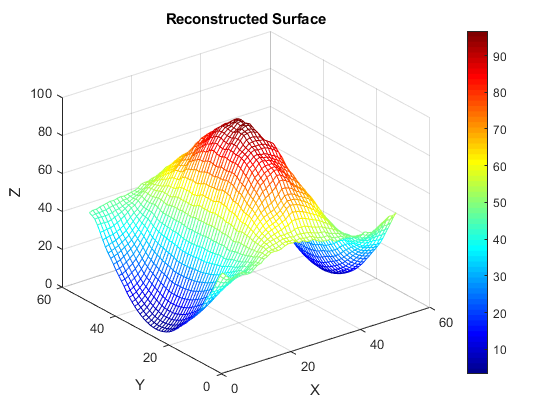

S=noisy_surface; 
SFR=S;       %forward smoothing vector 
N=length(S); 
alpha=.335;
% forward smothing of raws
for i=1:N
    for j=2:N
       SFR(i,j)=alpha*S(i,j)+(1-alpha)*SFR(i,j-1);
    end 
end 
% backward Smothing of raws. 
SBR=SFR; 
for i=1:N
    for j=N-1:-1:1
       SBR(i,j)=alpha*SFR(i,j)+(1-alpha)*SBR(i,j+1); 
    end
end 
% forward smothing of columns.
SFC=SBR;
for j=1:N
    for i=2:N
         SFC(i,j)=alpha*SBR(i,j)+(1-alpha)*SFC(i-1,j);
    end 
end 
%  backward smothing of columns.
SBC=SFC;

for j=1:N
    for i=N-1:-1:1
         SBC(i,j)=alpha*SFC(i,j)+(1-alpha)*SBC(i+1,j);
    end 
end 

figure()
mesh(SBC)      
colormap jet
colorbar 
title('Reconstructed Surface')
xlabel('X')
ylabel('Y')
zlabel('Z')   

`figure(4) reconstructed surface after forward-backward`

Plotting both graphs and comparing them visually, it can be seen that they look visually the same, in terms of surface behavior, with the smoothed measurments a bit noisier. The smoothed data values are slightly less than the true values in the peaks and the troughs, which can be related to conclusions and analysis of the previous assignments, but in 3D now.

Reconstructed=reshape(SBC,[],1); 
Varianc2=(1/(length(Reconstructed)-1))*sum((Reconstructed-True).^2)

Varianc2 = 7.1418

The Variance of item 3 was equal to 129.1469 while the variance of the smoothed data was equal to 6.5624 which is much less and a very small error between it and the true surface. This variance number indicates a good estimate of the results compared to the true trajectory which means we can rely on this model for this particular case and other similar cases.

**2.4) Try greater and smaller values of smoothing coefficient **$\alpha \;$**and explain the affect on estimation results.**

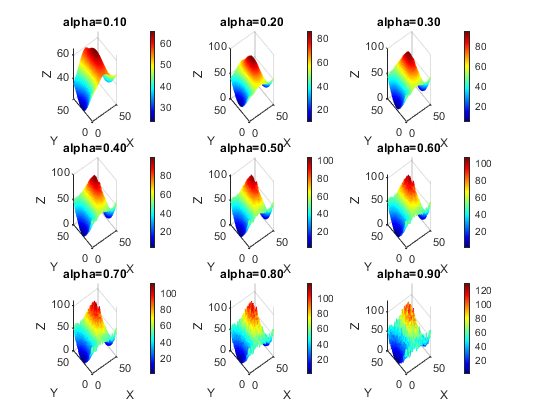

load('noisy_surface.mat')
load('true_surface.mat')

noisy=noisy_surface;
true=true_surface;

[x,y]=size(true);
Z=noisy;
k=0;
for alpha=0.1:0.1:0.9 
    k=k+1;
    Zs1=Z;
    for j=1:y % forward smothing of raws
        for i=2:x
            Zs1(i,j)=Zs1(i-1,j)+alpha*(Z(i,j)-Zs1(i-1,j));
        end
    end
    Zs2=Zs1;

    for j=1:y % backward smothing of raws
        for i=x-1:-1:1
            Zs2(i,j)=Zs2(i+1,j)+alpha*(Zs1(i,j)-Zs2(i+1,j));
        end
    end

    Zs3=Zs2;

    for i=1:x % forward smothing of Columns
        for j=2:y
            Zs3(i,j)=Zs3(i,j-1)+alpha*(Zs2(i,j)-Zs3(i,j-1));
        end
    end

    Zs4=Zs3;

    for i=1:x % Backward smothing of Columns
        for j=y-1:-1:1
            Zs4(i,j)=Zs4(i,j+1)+alpha*(Zs3(i,j)-Zs4(i,j+1));
        end
    end
    
    subplot(3,3,k)
    mesh(Zs4)
    colormap jet;
    colorbar
    s= 'alpha=';
    s2=sprintf('%.2f',alpha); 
    s3=strcat(s,s2); 
    title(s3); 
    xlabel('X'); ylabel('Y'); zlabel('Z');
end

Using a step of 0.1 between 0.1 and 0.9 for different values of alpha the result was, as predicted, for lower values of alpha the graph became smoother but deviated from the real trajectory and for a value like 0.1 it deviated from both the surface trend and the values and this can be explained as the model was approaching a plane with low value of alpha, like in 2D how the alpha follow a line in over-smoothed conditions, and for values higher than 0.4 the surface became more susceptible to noise and followed the noise rather than the true trajectory, or in other words we inclined to trust the measurements.

# learning log

In this assignment we rather enhanced our understanding of running mean and exponential smoothing, with real data used not knowing the true trajectory in the first part and with using the 3D surface in the second part, and if we conclude in bullet points:

1-      In a real application where we don’t know the true trajectory, practical and common sense of the analyzer is all he got, because all of the analysis tools are available and can easily be implemented but the sense of real numbers isn’t.

2-      Models built with measurement data with no prior knowledge of the true trajectory isn’t to be trusted unless experimented more and more, and verified for measurements.

3-      Using smoothing either in 2-D or in 3-D will have the same drawbacks, like the shift between the model and the true values or the change of the value of alpha and its effect on data. And regarding this point we tried to reflect on old results in previous assignments and used only forward smoothing of the data to see if it is applicable or not and as predicted the model was shifted to the right and had this inherent delay in the exponential smoothing method. Also examin the variance of smoothed  data to see the effect of on the error variance. 

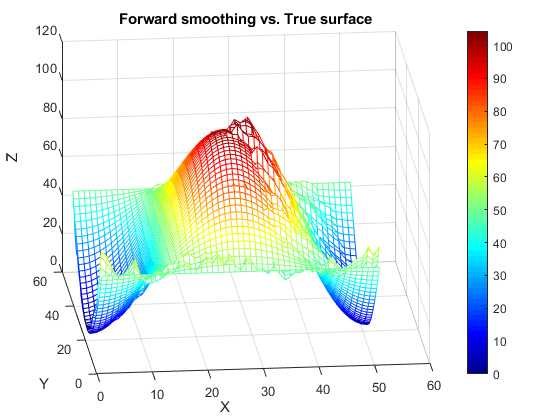

load('noisy_surface.mat')
load('true_surface.mat')

noisy=noisy_surface;
true=true_surface;

figure()

mesh(true)
colormap jet
[x,y]=size(true);
N=x*y;
Z=noisy;
Zs1=Z;
alpha=0.335;
for j=1:y % forward smothing of Raws
    for i=2:x
        Zs1(i,j)=Zs1(i-1,j)+alpha*(Z(i,j)-Zs1(i-1,j));
    end
end
Zs3=Zs1;

for i=1:x % forward smothing of Columns
    for j=2:y
        Zs3(i,j)=Zs3(i,j-1)+alpha*(Zs1(i,j)-Zs3(i,j-1));
    end
end

hold on
mesh(Zs3)
colorbar
title('Forward smoothing vs. True surface')
xlabel('X'); ylabel('Y'); zlabel('Z');
view([-6 24])

VarianceMatrixS=(Zs3-true).^2;

VarianceS=(1/(N-1))*sum(reshape(VarianceMatrixS,[],1)) % variance of the forward smoothing in raws and columns 

VarianceS = 45.7596

. As predicted the the value of the variance was higher (50.4899). 

function I = varI(s) % Function to calculate the variability indecator.
   n=length(s); 
   d=1:n-2;
   for j=1:n-2
       d(j)=s(j+2)+s(j)-2*s(j+1);
   end
   I=sum(d.^2); 
end 